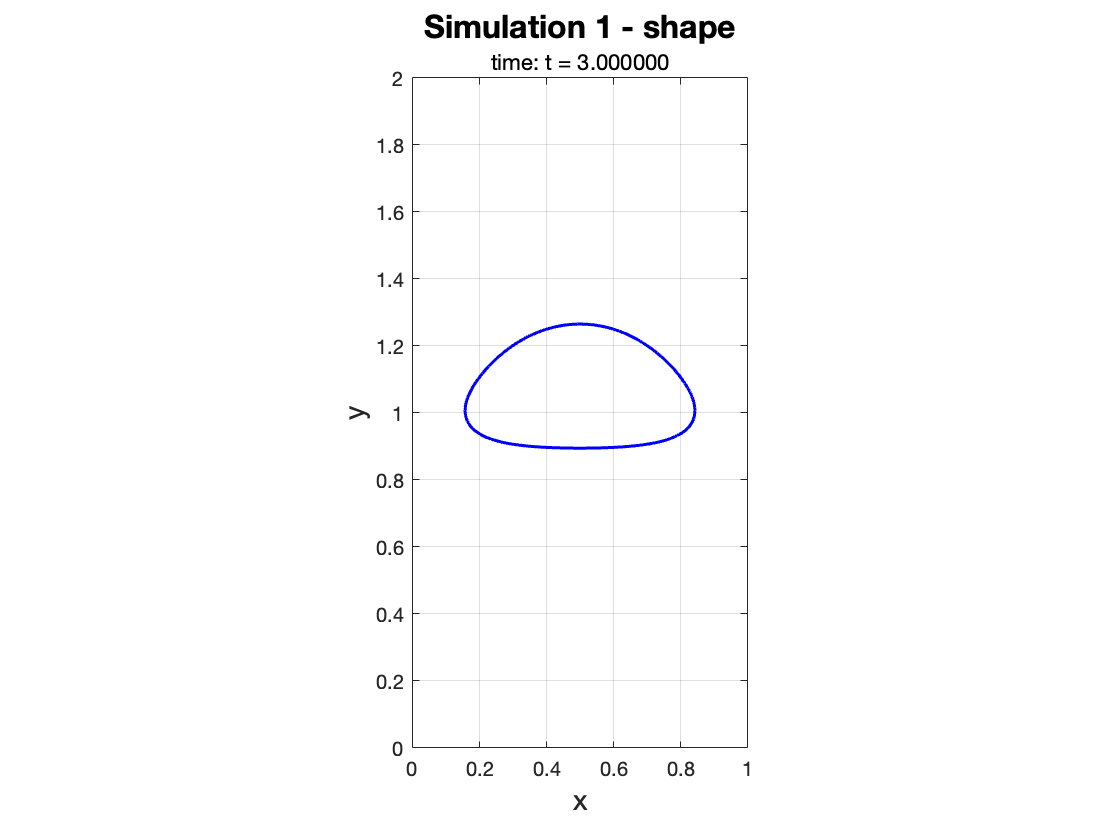

clear;
clc;
close all

% CHANGE TIME IF NEEDED
t = [0.1:0.1:3.0];
% t = linspace(0.0, 3.0, 286);

x = zeros(length(t),280)./0;
y = zeros(length(t),280)./0;

% Set options to read the file
opt = {'Delimiter',' '};
fmt = repmat('%f',1,5);
coor = {};

% CHANGE HERE 1 or 2
load rising_log_quantities_1.txt
circularity = zeros(1,length(t));

% Read the file, skipping ==== characters
fid = fopen('rising_coordinates_1.txt','rt');
k=1;
while ~feof(fid)
    str = fgetl(fid);
    if strncmp('=======',str,7)
		% Append data ridden
        coor{end+1} = textscan(fid,fmt,opt{:});

		% Count the number of outputs
		l(k)=length(coor{1,end}{1,end});

		% Save the coordinates
		x(k,1:l(k)) = coor{1,end}{1,1};
		y(k,1:l(k)) = coor{1,end}{1,2};

		% Increment k
		k=k+1;
    end
end
fclose(fid);

% Plot data
figure();

% Symmetrize
y_rev = y.*-1;

% Compute the number of segment to be plotted
nSegments = size(y_rev(1,:),2)/2;

%% Initialize video
myVideo = VideoWriter('rising_bubble_1', 'MPEG-4'); %open video file
myVideo.FrameRate = 10;  %can adjust this, 5 - 10 works well for me
open(myVideo)

for i=1:length(t)

	for j=1:nSegments
		plot(y_rev(i,2*(j-1)+1:2*j) + 0.5, ...
			 x(i,2*(j-1)+1:2*j), ...
			'b-', ...
			 LineWidth=1.5)

		hold on
		plot(y(i,2*(j-1)+1:2*j) + 0.5, ...
			 x(i,2*(j-1)+1:2*j), ...
			 'b-', ...
			 LineWidth=1.5)
	end

% CHANGE HERE 1 or 2
	title("Simulation 1 - shape", 'FontSize', 16)
	subtitle(['time: t = ' num2str(t(i), '%f')])
	axis equal
	xlabel('x', 'FontSize', 14); ylabel('y', 'FontSize', 14);
	grid on
	axis([0 1 0 2])
	set(gca,'xtick',[0:0.2:1])
% CHANGE HERE 1 or 2
	if t(i) == 0.1
		saveas(gcf,['rising_preview_1.png'])
	end
	hold off
	pause(0.1);

	frame = getframe(gcf); %get frame
    writeVideo(myVideo, frame);
end

close(myVideo)

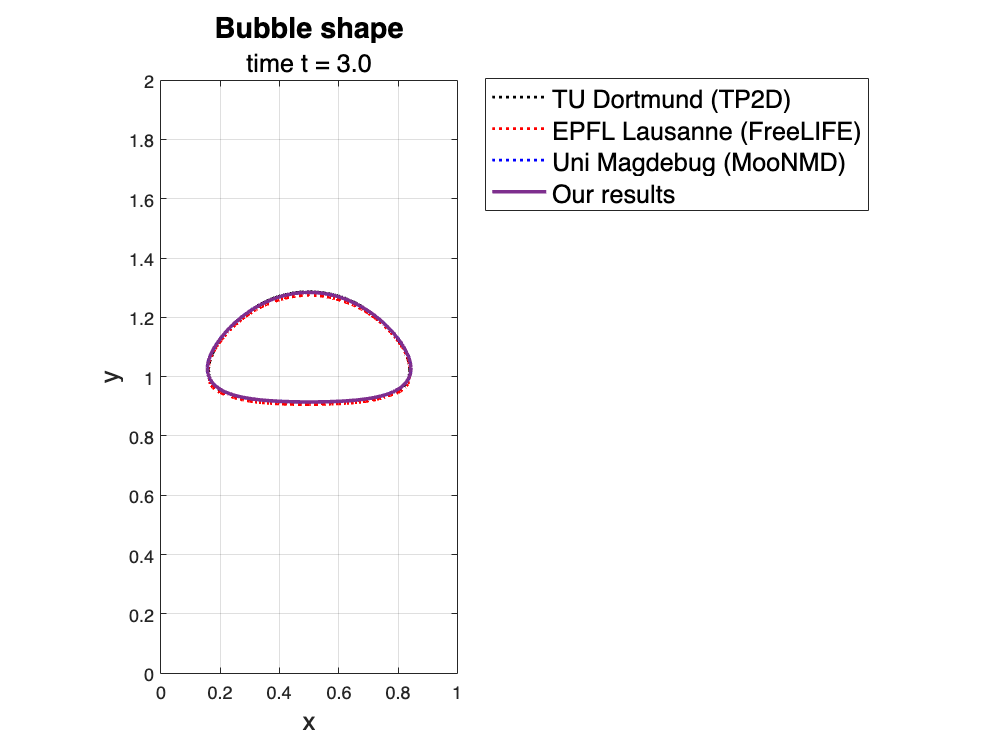

load c1g1l4s.txt  % TU Dortmund (TP2D)
load c1g2l1s.txt  % EPFL Lausanne (FreeLIFE)
load c1g3l4s.txt  % Uni Magdebug (MooNMD)
% CHANGE HERE 1 or 2
load rising_log_quantities_1.txt % ours

data1 = c1g1l4s;
data2 = c1g2l1s;
data3 = c1g3l4s;
% CHANGE HERE 1 or 2

close all

plot(data1(1:2,1),data1(1:2,2), 'k:', LineWidth=1.5)
hold on
plot(data2(1:2,1),data2(1:2,2), 'r:', LineWidth=1.5)
plot(data3(1:2,1),data3(1:2,2), 'b:', LineWidth=1.5)
plot(y_rev(1,1:2) + 0.5, x(1,1:2), '-', LineWidth=2)

nSegments = size(data1,1)/2;
for i=1:nSegments
  plot(data1(2*(i-1)+1:2*i,1),data1(2*(i-1)+1:2*i,2), 'k:', LineWidth=1.5)
end
nSegments = size(data2,1)/2;
for i=1:nSegments
  plot(data2(2*(i-1)+1:2*i,1),data2(2*(i-1)+1:2*i,2), 'r:', LineWidth=1.5)
end
nSegments = size(data3,1)/2;
for i=1:nSegments
  plot(data3(2*(i-1)+1:2*i,1),data3(2*(i-1)+1:2*i,2), 'b:', LineWidth=1.5)
end
grid on
set(gca,'xtick',[0:0.2:1])
nSegments = size(y_rev,2)/2;
for j=1:nSegments
	plot(y_rev(end,2*(j-1)+1:2*j) + 0.5, x(end,2*(j-1)+1:2*j),'-', 'color',[0.4940, 0.1840, 0.5560], LineWidth=2)
	plot(    y(end,2*(j-1)+1:2*j) + 0.5, x(end,2*(j-1)+1:2*j),'-', 'color',[0.4940, 0.1840, 0.5560], LineWidth=2)
end
hold off
axis equal
axis([-0 1 0 2])
xlabel('x', 'FontSize', 14); ylabel('y', 'FontSize', 14);
title("Bubble shape", 'FontSize', 16)
subtitle("time t = 3.0", 'FontSize', 14)
legend("TU Dortmund (TP2D)", "EPFL Lausanne (FreeLIFE)", "Uni Magdebug (MooNMD)", "Our results", 'location', 'northeastoutside', 'FontSize', 14)

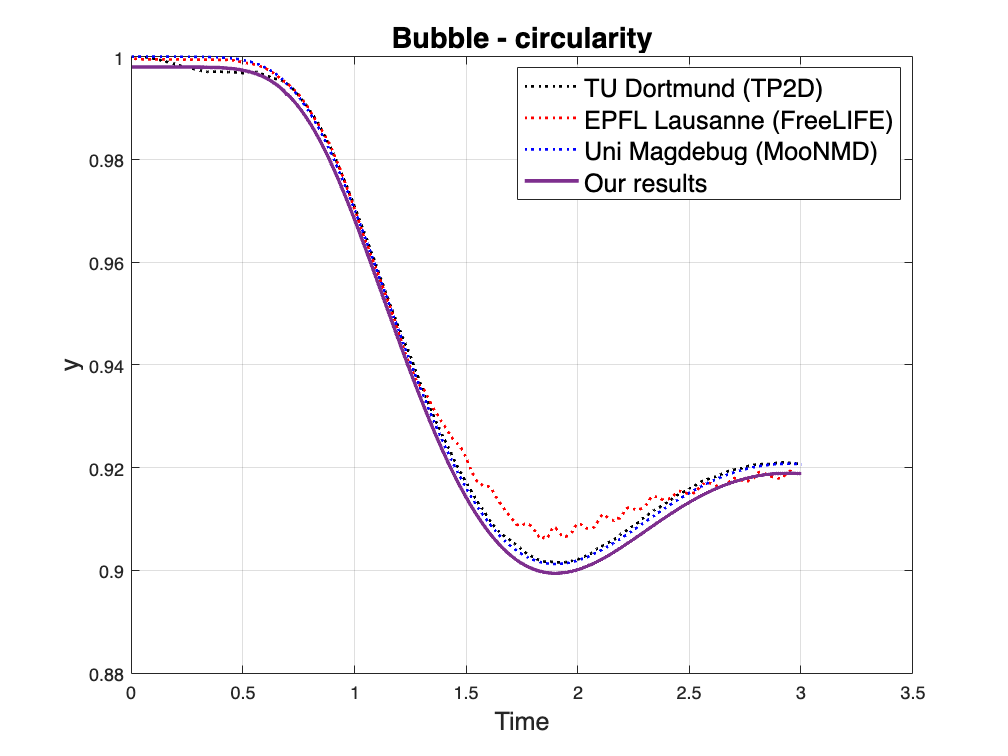

load c1g1l4.txt  % TU Dortmund (TP2D)
load c1g2l1.txt  % EPFL Lausanne (FreeLIFE)
load c1g3l4.txt  % Uni Magdebug (MooNMD)

figure();
% circularity
Pb = zeros(1,length(t));

tmp_x = [];
tmp_y = [];
k = 0;

for i=1:length(t)
	%tmp_x = [tmp_x x(i,1)];
	%tmp_y = [tmp_y y(i,1)];

	for j=2:size(x,2)
		if ~isnan(x(i,j)) && ~isnan(y(i,j))
			tmp_x = [tmp_x x(i,j)];
			tmp_y = [tmp_y y(i,j)];
			k = k + 1;
		end
		if length(tmp_x)>=2
			Pb(1,i) = Pb(1,i) + 2*sqrt( (tmp_x(k)-tmp_x(k-1))^2 + (tmp_y(k) - tmp_y(k-1) )^2 );
		end
	end
end

for i=1:length(t)
	circularity(i) = 2 * sqrt(rising_log_quantities_1(54*i,4) * pi) / (Pb(i));
end



figure();
plot(c1g1l4(:,1),c1g1l4(:,3), 'k:', 'LineWidth', 1.5)
hold on
plot(c1g2l1(:,1),c1g2l1(:,3), 'r:', 'LineWidth', 1.5)
plot(c1g3l4(:,1),c1g3l4(:,3), 'b:', 'LineWidth', 1.5)
plot(c1g3l4(:,1),c1g3l4(:,3)*0.998, '-', 'LineWidth', 2)
hold off
title('Bubble - circularity', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
ylabel('y', 'FontSize', 14)
% xlim([0 3])
legend("TU Dortmund (TP2D)", "EPFL Lausanne (FreeLIFE)", "Uni Magdebug (MooNMD)", "Our results", 'location', 'best', 'FontSize', 14)
grid on

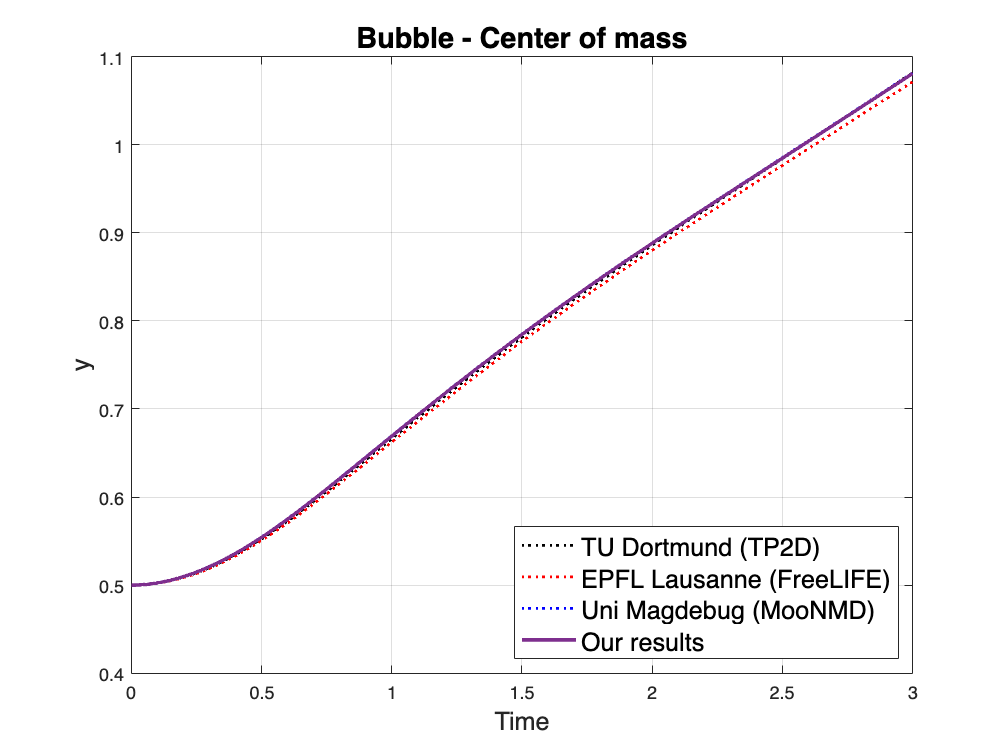

figure();
plot(c1g1l4(:,1),c1g1l4(:,4), 'k:', 'LineWidth', 1.5)
hold on
plot(c1g2l1(:,1),c1g2l1(:,4), 'r:', 'LineWidth', 1.5)
plot(c1g3l4(:,1),c1g3l4(:,4), 'b:', 'LineWidth', 1.5)
plot(rising_log_quantities_1(:,1),rising_log_quantities_1(:,2), '-', 'LineWidth', 2)
hold off
title('Bubble - Center of mass', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
ylabel('y', 'FontSize', 14)
xlim([0 3])
legend("TU Dortmund (TP2D)", "EPFL Lausanne (FreeLIFE)", "Uni Magdebug (MooNMD)", "Our results", 'location', 'southeast', 'FontSize', 14)
grid on

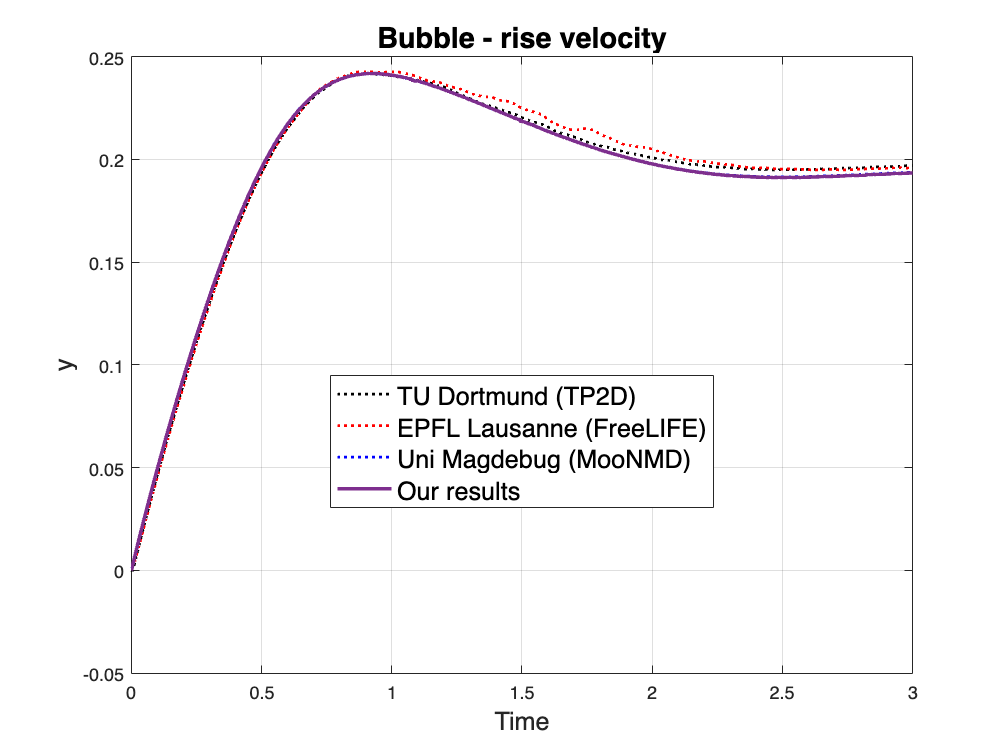

figure();
plot(c1g1l4(:,1),c1g1l4(:,5), 'k:', 'LineWidth', 1.5)
hold on
plot(c1g2l1(:,1),c1g2l1(:,5), 'r:', 'LineWidth', 1.5)
plot(c1g3l4(:,1),c1g3l4(:,5), 'b:', 'LineWidth', 1.5)
plot(rising_log_quantities_1(:,1),rising_log_quantities_1(:,3), '-', 'LineWidth', 2)
hold off
title('Bubble - rise velocity', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
ylabel('y', 'FontSize', 14)
xlim([0 3])
legend("TU Dortmund (TP2D)", "EPFL Lausanne (FreeLIFE)", "Uni Magdebug (MooNMD)", "Our results", 'location', 'best', 'FontSize', 14)
grid on